# Exam B Question 3

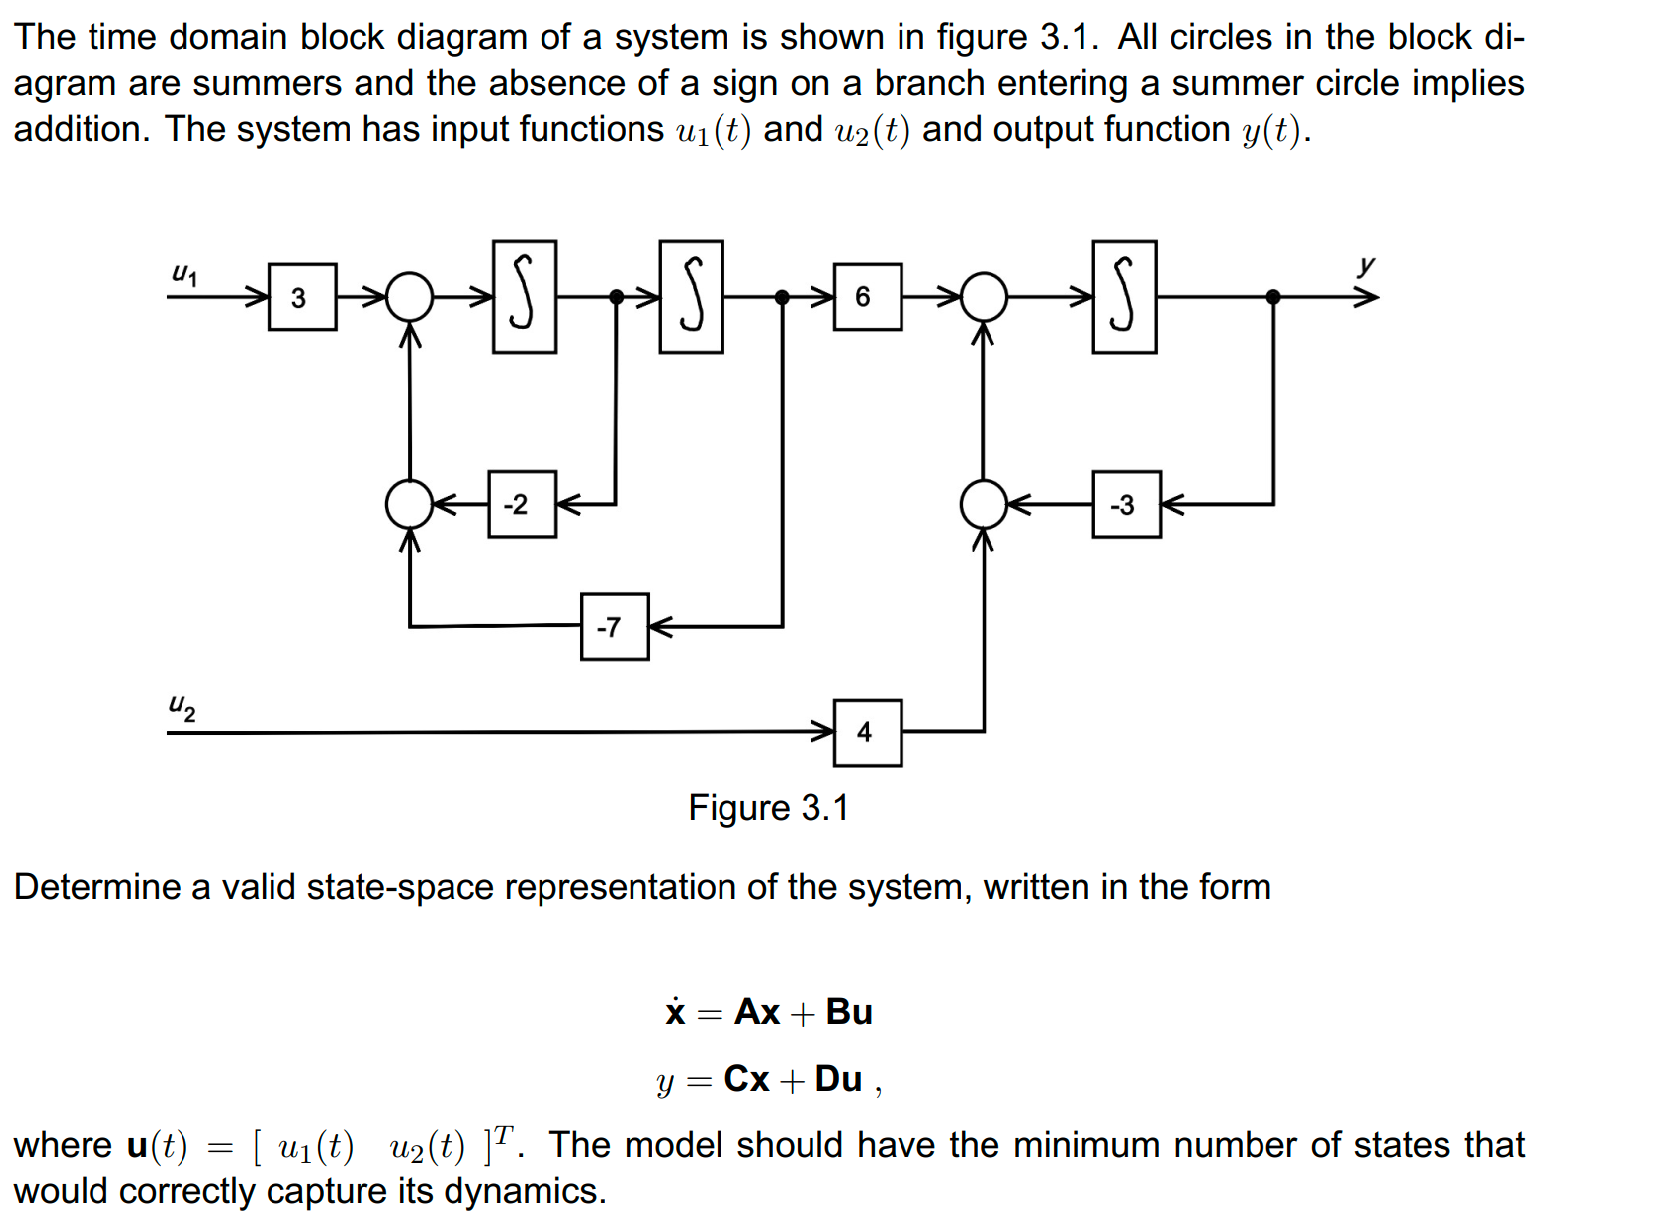

The state-space system is:


$$\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } \\
\dot{x_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-3 & 6 & 0\\
0 & 0 & 1\\
0 & -7 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 4\\
0 & 0\\
3 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


A = [-3 ,6, 0;
     0,  0, 1;
     0, -7, -2];
B = [0, 4;
     0, 0;
     3, 0];
C = [1, 0, 0];
D = 0;

n = rank(A,1)

n = 2

## (b) controllaility and observability

Ob = obsv(A,C)

Ob =      1     0     0
    -3     6     0
     9   -18     6


fprintf('Observability matrix rank: %d (should be %d)\n', rank(Ob), n);

Observability matrix rank: 3 (should be 2)


Cb = ctrb(A,B)

Cb =      0     4     0   -12    18    36
     0     0     3     0    -6     0
     3     0    -6     0    -9     0


fprintf('Controlability matrix rank: %d (should be %d)\n', rank(Cb), n);

Controlability matrix rank: 3 (should be 2)


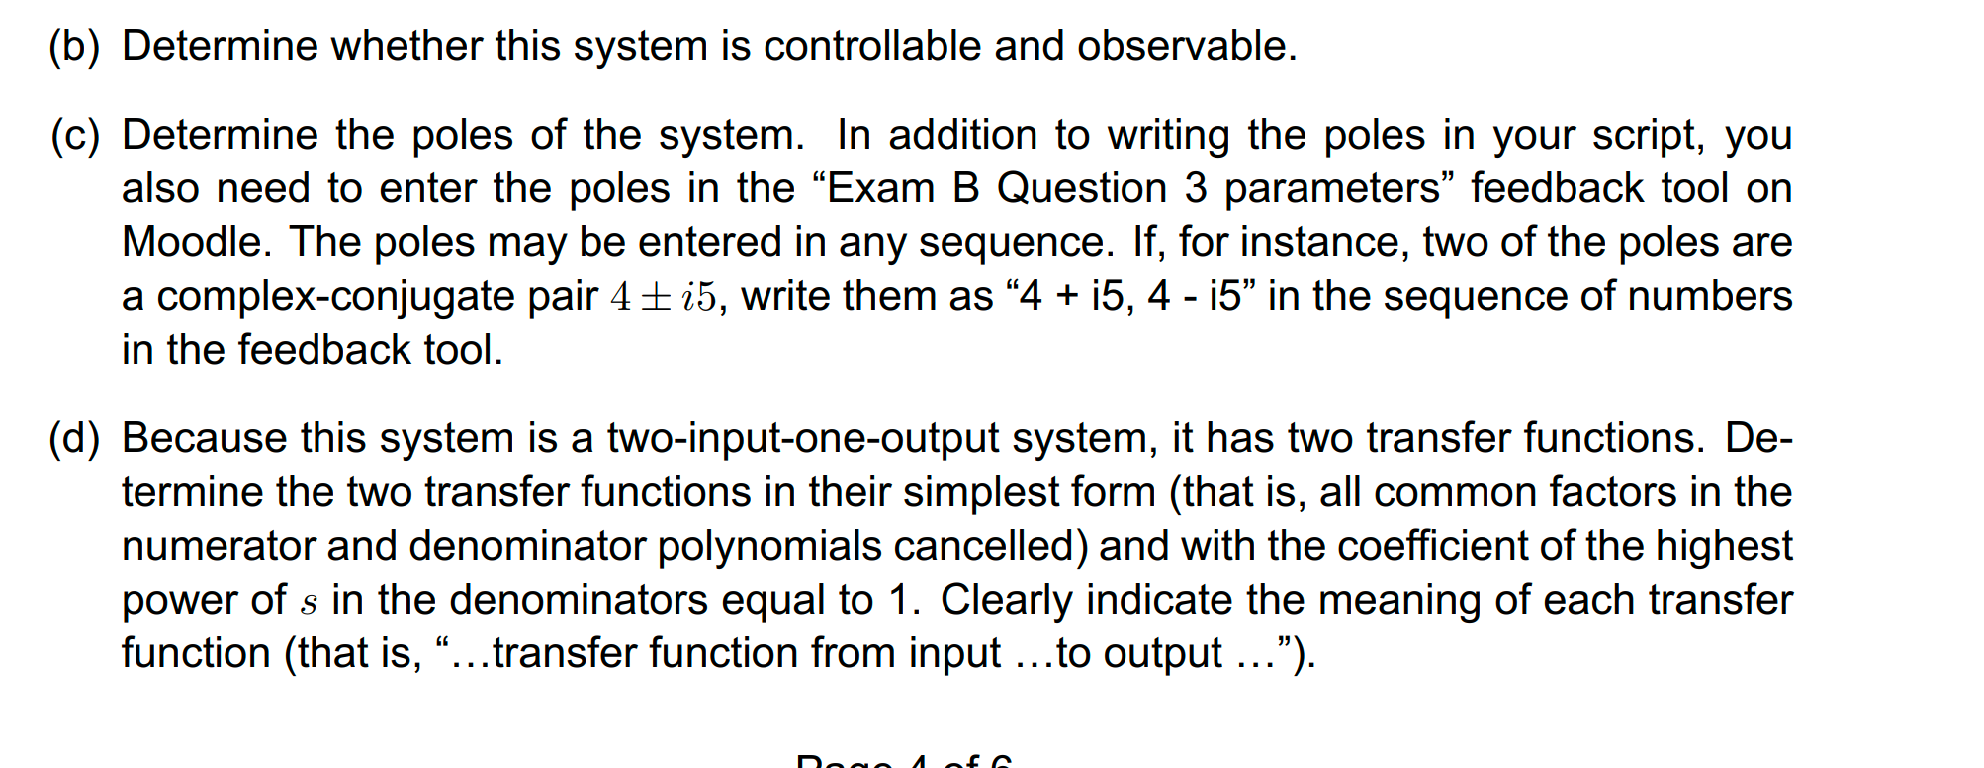

## (c) poles of the system

poles = eig(A);
fprintf('the poles of the system are \n');

the poles of the system are 


display(poles);

poles =   -3.0000 + 0.0000i
  -1.0000 + 2.4495i
  -1.0000 - 2.4495i


## (d) transfer function

G = minreal(tf(ss(A,B,C,D)))


G =
 
  From input 1 to output:
            18
  -----------------------
  s^3 + 5 s^2 + 13 s + 21
 
  From input 2 to output:
    4
  -----
  s + 3
 
Continuous-time transfer function.
